# Systematic review of SysID - Subspace identification

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Jingxiao Liu
% Inferlab, CEE, CMU
% June, 2019
% Matlab live script for introducing subspace identification
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Part 4. Subspace State Space System IDentification (4SID) 

For stochastic system!

### **4.1 The state space model:**


$$\begin{array}{l}
x_{k+1} =A\;x_k +B\;u_k +w_k \\
y_k =C\;x_k +D\;u_k +v_k \\
E\left\lbrack w_k w_k \right\rbrack =Q\\
E\left\lbrack v_k v_k \right\rbrack =R\\
E\left\lbrack w_k v_k \right\rbrack =S
\end{array}$$


It can be split up into a deterministic and a stochastic subsystem. Deterministic subsystem:


$$\begin{array}{l}
x_{k+1}^d =A\;x_k^d +B\;u_k \\
y_k^d =C\;x_k^d +D\;u_k 
\end{array}$$


Stochastic subsystem:


$$\begin{array}{l}
x_{k+1}^s =A\;x_k^s +w_k \\
y_k^s =C\;x_k^s +v_k 
\end{array}$$


This process can be also represent by Kalman filter:

$\begin{array}{l}
{\hat{x} }_{k+1} =A\;{\hat{x} }_k +B\;u_k +K\left(y_k -C{\hat{x} }_k +D\;u_k \right)\\
y_k =C\;\hat{x_k } +D\;u_k +\left(y_k -C{\hat{x} }_k +D\;u_k \right)
\end{array}$,

where *K* is the Kalman gain.

Define $e_k =\left(y_k -C{\hat{x} }_k +D\;u_k \right)$

Then, we also have the following form:


$$\begin{array}{l}
x_{k+1} =A_K x_k +B_k \;z_k \\
y_k =C\;x_k +D\;u_k +e_k 
\end{array}$$


where,

$z_k =\left\lbrack u_k^T ,y_k^T \right\rbrack ,{\;A}_k =A-K\;C,B_k =\left\lbrack B-K\;D,K\right\rbrack$.

### **4.2 Define matrices**

The extended observability matrix $\Gamma$:


$$\Gamma_i =\left\lbrack \begin{array}{c}
C\\
C\;A\\
C\;A^2 \\
\cdots \\
C\;A^{i-1} 
\end{array}\right\rbrack$$


The reversed extended controllability matrix $\Delta_i^d$:


$$\Delta_i^d =\left\lbrack \begin{array}{ccccc}
A^{i-1} B & A^{i-2} B & \cdots  & A\;B & B
\end{array}\right\rbrack$$


The lower block triangular Toeplitz matrix $H_i^d$:


$$H_i^d =\left\lbrack \begin{array}{ccccc}
D & 0 & 0 & \cdots  & 0\\
C\;B & D & 0 & \cdots  & 0\\
C\;A\;B & C\;B & D & \cdots  & 0\\
\cdots  & \cdots  & \cdots  & \cdots  & \cdots \\
C\;A^{i-2} B & C\;A^{i-3} B & C\;A^{i-4} B & \cdots  & D
\end{array}\right\rbrack$$


The past input and output block Hankel matrices are:


$$U_{0|i-1} =\left\lbrack \begin{array}{ccccc}
u_0  & u_1  & u_2  & \cdots  & u_{j-1} \\
u_1  & u_2  & u_3  & \cdots  & u_j \\
\cdots  & \cdots  & \cdots  & \cdots  & \cdots \\
u_{i-1}  & u_i  & u_{i+1}  & \cdots  & u_{i+j-2} 
\end{array}\right\rbrack$$



$$Y_{0|i-1} =\left\lbrack \begin{array}{ccccc}
y_0  & y_1  & y_2  & \cdots  & y_{j-1} \\
y_1  & y_2  & y_3  & \cdots  & y_j \\
\cdots  & \cdots  & \cdots  & \cdots  & \cdots \\
y_{i-1}  & y_i  & y_{i+1}  & \cdots  & y_{i+j-2} 
\end{array}\right\rbrack$$


Similarly, the future input and output block Hankel matrices are:

$U_{i\left|2i-1\right.}$, $Y_{i\left|2i-1\right.}$.

The past and future deterministic state matrices:


$$\begin{array}{l}
X_0^d =\left\lbrack \begin{array}{ccccc}
x_0^d  & x_1^d  & x_2^d  & \cdots  & x_{j-1}^d 
\end{array}\right\rbrack ,\\
X_i^d =\left\lbrack \begin{array}{ccccc}
x_i^d  & x_{i+1}^d  & x_{i+2}^d  & \cdots  & x_{i+j-1}^d 
\end{array}\right\rbrack \ldotp 
\end{array}$$
 

Then, we have the matrix input-output equations:


$$\begin{array}{l}
Y_{0|i-1} =\Gamma_i X_0^d +H_i^d U_{0|i-1} +Y_{0|i-1}^s ,\\
Y_{i|2i-1} =\Gamma_i X_i^d +H_i^d U_{i|2i-1} +Y_{i|2i-1}^s ,\\
X_i^d =A^i X_0^d +\Delta_i^d U_{0|i-1} \ldotp 
\end{array}$$


In Kalman form, the first equation above can be written as:


$$Y_{i\left|2i-1\right.} =\Gamma_i X_i^d +H_i^d U_{i\left|2i-1\right.} +G_{i|2i-1} E_{i|2i-1}$$


where,


$$G_{i\left|2i-1\right.} =\left\lbrack \begin{array}{ccccc}
I & 0 & 0 & \cdots  & 0\\
C\;K & I & 0 & \cdots  & 0\\
C\;A\;K & C\;K & I & \cdots  & 0\\
\cdots  & \cdots  & \cdots  & \cdots  & \cdots \\
C\;A^{i-2} K & C\;A^{i-3} K & C\;A^{i-4} K & \cdots  & I
\end{array}\right\rbrack$$


Also, for a large *i*, $A^i X_0^d \approx 0$, thus,


$$Y_{i\left|2i-1\right.} =\Gamma_i \Delta_i^d U_{0\left|i-1\right.} +H_i^d U_{i\left|2i-1\right.} +G_{i\left|2i-1\right.} E_{i\left|2i-1\right.}$$


### **4.3 The main projection**

We all know the least squares solution for $Y=\beta \;X+w$ is:


$$\beta^ˆ ={Y\;X}^T {\left({X\;X}^T \right)}^{-1} \ldotp$$


The model prediction is:


$$\hat{Y} =\beta^ˆ X={Y\;X}^T {\left({X\;X}^T \right)}^{-1} X\ldotp$$


Then, the main projection is defined as 


$$Y\;/\;X=$$

$${Y\;X}^T {\left({X\;X}^T \right)}^{-1} X$$


It corresponds to the optimal prediction of $Y$ given $X$ in a sense that

${\left\|Y-Y/X\right\|}^2$.

### **4.4 The N4SID algorithm**

Estimate the observability matrix and the state by projecting future observations onto past observations:

$Y_{i\left|2i-1\right.} /U_{i|2i-1}^{\bot } =\Gamma_i \Delta_i^d U_{0\left|i-1\right.} /U_{i|2i-1}^{\bot } +H_i^d U_{i\left|2i-1\right.} /U_{i|2i-1}^{\bot } +G_{i\left|2i-1\right.} E_{i\left|2i-1\right.} /U_{i|2i-1}^{\bot }$.

Since the past input are uncorrelated with future input and future observation noise, thus,


$$\begin{array}{l}
U_{i\left|2i-1\right.} /U_{i|2i-1}^{\bot } =0\\
E_{i\left|2i-1\right.} /U_{i|2i-1}^{\bot } =E_{i\left|2i-1\right.} \left(I-U_{i|2i-1}^T {\left(U_{i|2i-1} U_{i|2i-1}^T \right)}^{-1} U_{i|2i-1} \right)=E_{i|2i-1} 
\end{array}$$


We can eliminate the above equation as:

$Y_{i\left|2i-1\right.} /U_{i|2i-1}^{\bot } =\Gamma_i \Delta_i^d U_{0\left|i-1\right.} /U_{i|2i-1}^{\bot } +G_{i\left|2i-1\right.} E_{i\left|2i-1\right.}$.

Then, we can remove the noise term by multiplying $U_{0\left|i-1\right.}$:

${\;Y}_{i\left|2i-1\right.} /U_{i\left|2i-1\right.}^T U_{0\left|i-1\right.} =\Gamma_i \Delta_i^d U_{0\left|i-1\right.} /U_{i\left|2i-1\right.}^T U_{0\left|i-1\right.} +G_{i\left|2i-1\right.} E_{i\left|2i-1\right.} U_{0\left|i-1\right.} =\Gamma_i \Delta_i^d U_{0\left|i-1\right.} /U_{i\left|2i-1\right.}^T U_{0\left|i-1\right.}$.

We can calcualte LHS using data, then perform SVD:


$${\;Y}_{i\left|2i-1\right.} /U_{i\left|2i-1\right.}^T U_{0\left|i-1\right.} =U\;S\;V^T$$


And choose $\Gamma_i =U\;S^{1/2} \;$.

Then we can calculate the transition matrix $\hat{A}$ from $\Gamma_i$.

### 4.5 Modal analysis

After obtaining $A$, we can perform an eigenvalue decomposition of it:


$$A=\Phi \left\lbrack \lambda_i \right\rbrack \Phi^{-1}$$


Then, find the discrete-time values, which are also modal frequencies:


$$\omega_i =\frac{\mathrm{ln}\left(\lambda_i \right)}{\Delta t}$$


Also, mode shape matrix:

$\psi =C\Phi$.

### 4.6 Implementation

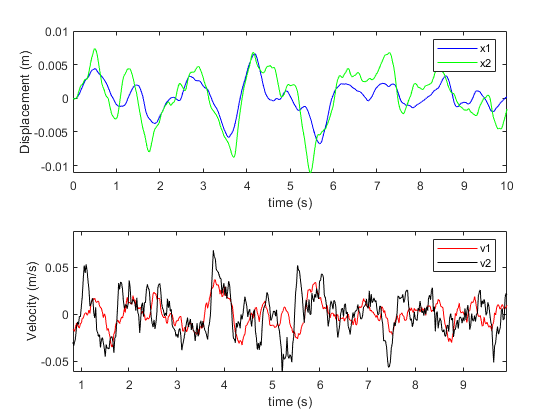

clc;
clear;
close all;
addpath ../functions/
T = 10; %length of time duration
nt = 500; %number of time stamps
Fs = nt/T;
tspan=linspace(0,T,nt);
F = csvread(['../data/ambient.csv']); %load data
ysol = csvread(['../data/2dof.csv']); %load data
tspan=linspace(0,T,nt);
figure(1)
plot_dv(tspan,ysol')

Matlab has a function to help us calculate the modal parameters:

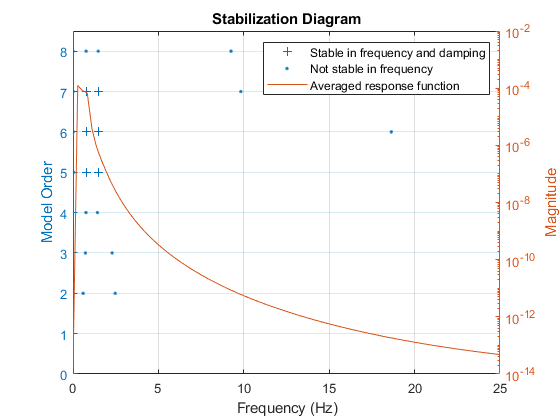

[frf,f] = modalfrf(F',ysol(3:4,:)',Fs,180,'Estimator','subspace','Order',30);
figure(2)
modalsd(frf,f,Fs,'MaxModes',8)